% Constants
constants;

% Perturbation magnitude
epsilon = 1e-8;

% Function for finding wrench given inputs
wrench = @(xi) getWrench(xi, params);

% Definition of screw
% omega = rand(3, 1);
% % omega = [0 0 0]';
% v = rand(3, 1);
% % v = [0 1 0]';
% xi = [omega; v];
% disp("Screw:")
% disp(xi)

% Minimal energy configuration screw
xi_min = [2.2214 0 2.2214 -1.7524 0 1.7524]';

% Analytical solution for stiffness matrix at given screw
% K_analytic = getStiffnessMatrix(xi, params);
K_analytic = getStiffnessMatrix(xi_min, params);

% Calculates the stiffness matrix numerically using the finite difference method
for i = 1:6
    dx = zeros(6,1); 
    dx(i) = epsilon;
    % wrench_plus = wrench(xi + dx);
    % wrench_minus = wrench(xi - dx);
    wrench_plus = wrench(xi_min + dx);
    wrench_minus = wrench(xi_min - dx);
    wrench_fd(:, i) = (wrench_plus - wrench_minus) / (2 * epsilon);
    
    % fprintf('Error in dwrench/dxi_%d: %e\n', i, norm(wrench_fd(:, i) - K_analytic(:, i))); 
end

% Full analytical and numerical solutions
disp("Analytical Solution:")

Analytical Solution:


disp(K_analytic)

   49.8268   10.3850  -26.7587  -48.5420   43.7033  -48.5405
  -21.1408   -0.0008  -21.1415  -26.8000   -0.0018   26.7991
   46.8561   -7.7092  -29.7302  -48.5408  -43.7033  -48.5416
 -100.8472   55.4068  -22.2341   49.8271   44.8613   49.8277
 -169.8148    0.0000  169.8310    0.0003   -0.0008    0.0003
  -22.2270  -41.1328  -69.1458  -29.7304   26.7670  -29.7299



disp("Numerical Solution:")

Numerical Solution:


disp(wrench_fd)

   49.8268   10.3850  -26.7587  -48.5420   43.7033  -48.5405
  -21.1408   -0.0008  -21.1415  -26.8000   -0.0018   26.7991
   46.8561   -7.7092  -29.7302  -48.5408  -43.7033  -48.5416
 -100.8472   55.4068  -22.2341   49.8271   44.8613   49.8277
 -169.8148    0.0000  169.8310    0.0003   -0.0008    0.0002
  -22.2270  -41.1328  -69.1458  -29.7304   26.7670  -29.7299






% Comparison between Analytical and Numerical results
Analytical = K_analytic; % Analytical matrix
Numerical  = wrench_fd; % Numerical matrix
relError = norm(Analytical - Numerical, "fro") / norm(Analytical, "fro")

relError = 2.9817e-08


% Calculation of the wrench change from the stiffness matrix and change in
% screw
dwrench = Analytical * xi_min;
% dwrench = Analytical * xi_min;
disp("Wrench:")

Wrench:


disp(dwrench)

   51.2460
    0.0012
   38.0422
 -273.4116
    0.0359
 -202.9747



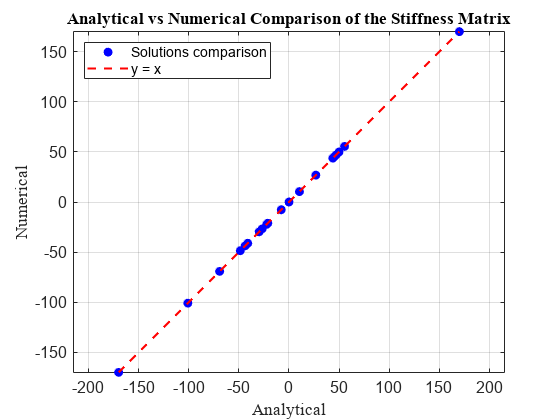


% Scatter Plot: Analytical vs Numerical
figure;
plot(Analytical(:), Numerical(:), 'bo', 'MarkerFaceColor','b');
hold on;
minVal = min([Analytical(:); Numerical(:)]);
maxVal = max([Analytical(:); Numerical(:)]);
plot([minVal, maxVal], [minVal, maxVal], 'r--', 'LineWidth', 1.5); % y = x line
xlabel('Analytical', 'FontName', "Times New Roman");
ylabel('Numerical', 'FontName', "Times New Roman");
title('Analytical vs Numerical Comparison of the Stiffness Matrix', 'FontName', "Times New Roman");
legend("Solutions comparison", "y = x", "Location", "northwest")
grid on;
axis equal;
set(gca, 'FontSize', 12);


% % Annotate with R^2 correlation
% R = corrcoef(Analytical(:), Numerical(:));
% text(minVal, maxVal, sprintf('R^2 = %.6f', R(1,2)^2), ...
%     'VerticalAlignment','bottom', 'FontSize', 12, 'BackgroundColor','w');
